W systemach dynamicznych wartości sygnałów wyjściowych zależą zarówno od chwilowych wartości sygnałów wejściowych, jak i od przeszłego zachowania systemu. 

Na przykład fotel samochodowy to system dynamiczny — kształt fotela (pozycja ustalona) zależy zarówno od aktualnej wagi pasażera (wartość chwilowa), jak i od tego, jak długo pasażer przebywa w samochodzie (zachowanie przeszłe).

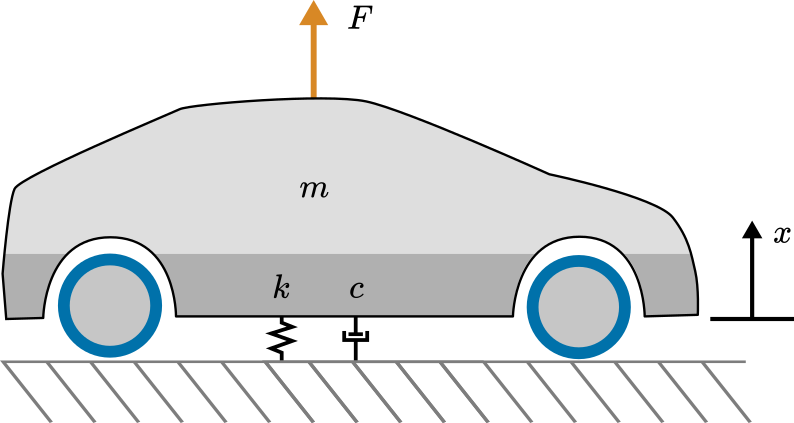 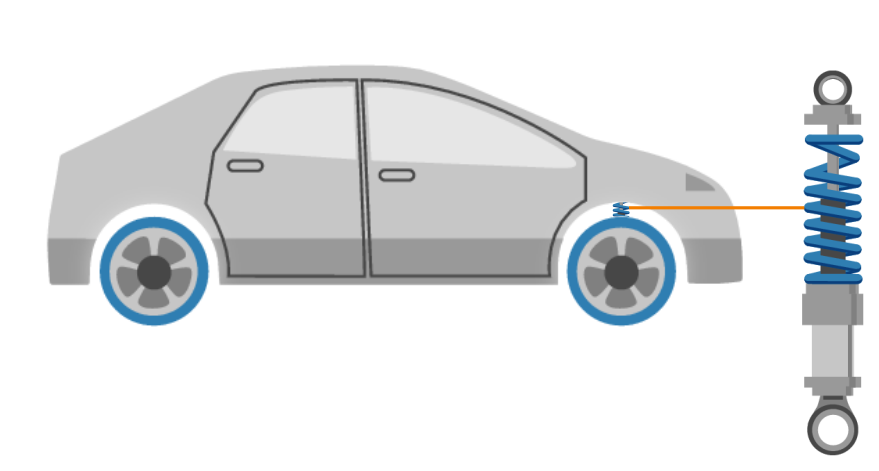  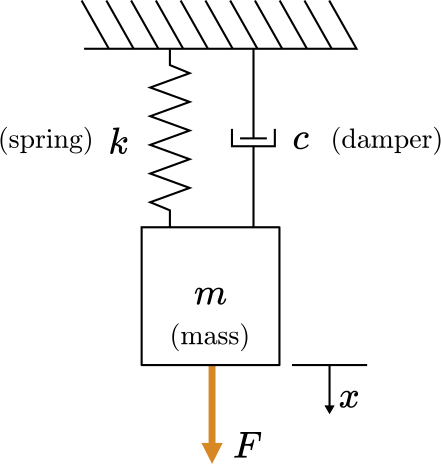 

Rys 1 Schemat układu masa-tłumik-sprężyna

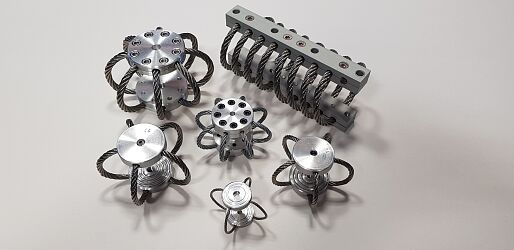

Rys. 2 Przykład modelowanego układu stosowany na okrętach MW (producent OBR CTM)

Modelowany układ jest  przykładem stosowanego na okretach MW amortyzatorów przeciwudarowych. 

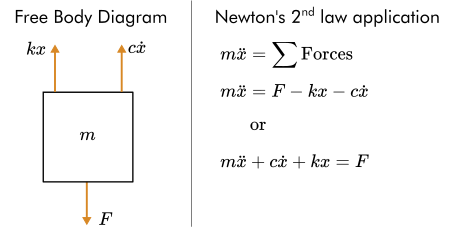

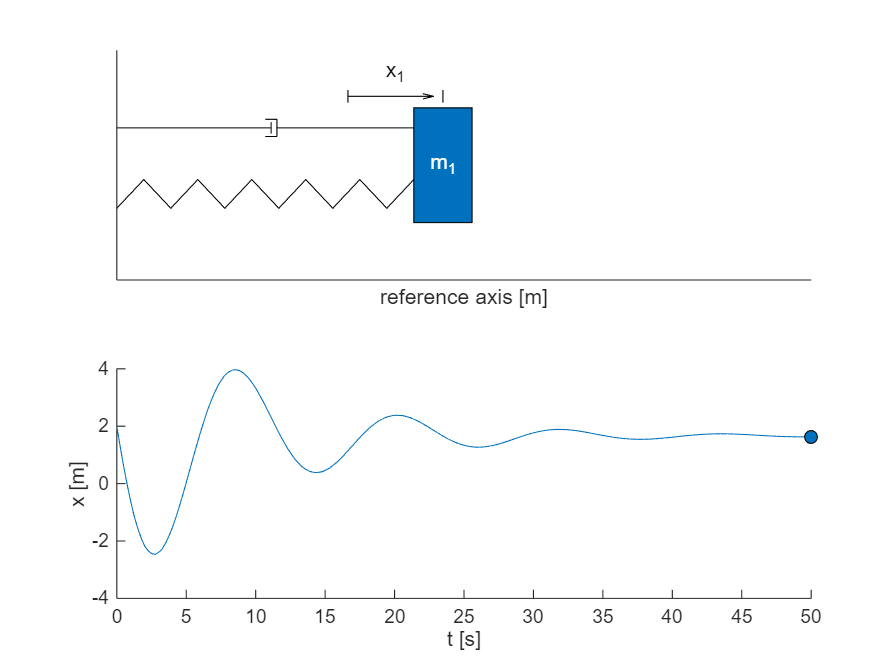

warning off
n = 200; % The number of steps used in the visualization
visualize = true; % Click the checkbox to show the visualization
if(visualize)
    simOut = sim("msdSimulationOutput_PP"); % Run the Simulink model
    animateMSD(simOut.tout,simOut.yout,0.5,n)
end

Model to matematyczna relacja między zmiennymi wejściowymi i wyjściowymi systemu. Modele systemów dynamicznych są zazwyczaj opisywane za pomocą:

- równań różniczkowych lub różnicowych,

- równań w przestrzeni stanów,

Modele dynamiczne mogą być reprezentowane zarówno w formie czasu ciągłego, jak i dyskretnego.

Często wykorzystywanym przykładem modelu dynamicznego jest równanie ruchu układu sprężyna-masa-tłumik. W takim systemie masa porusza się w odpowiedzi na siłę F(t), która działa na podstawę połączoną z masą. Sygnałem wejściowym systemu jest siła F(t), a sygnałem wyjściowym przemieszczenie x(t).


$$m\ddot{x} \;=\;\;\sum F$$



$$m \frac{d^2x}{dt^2} \;=\;\;\sum F$$


Typowy przykład dynamicznego modelu to równanie ruchu dla układu masy, sprężyny i tłumika:

$m \frac{d^2 x(t)}{dt^2} + c \frac{dx(t)}{dt} + k x(t) = F(t)$         (1)

gdzie:

m to masa,

k to stała sztywności sprężyny,

c to współczynnik tłumienia.

Rozwiązanie tego równania pozwala wyznaczyć przemieszczenie masy y(t) w funkcji siły zewnętrznej F(t).

## Model z wykorzystaniem ODE

**ODE (ordinary differential equation)**, czyli zwyczajne równanie różniczkowe, to równanie matematyczne, które opisuje relacje między zmienną niezależną t (zazwyczaj czasem) a jedną lub więcej funkcji zależnych y(t), oraz ich pochodnymi.

    % Parametry układu
    m = 1.0;       % masa (kg)
    k = 10;       % współczynnik sprężystości sprężyny (N/m)
    b = 1;        % współczynnik tłumienia (Ns/m)

    % Warunki początkowe
    x0 = 10;        % początkowe przemieszczenie (m)
    v0 = 1;        % początkowa prędkość (m/s)

    % Czas symulacji i krok czasowy
    t0 = 0;        % czas początkowy
    tf = 10;       % czas końcowy

Definiujemy tylko czas początku i końca symulacji, gdyż model jest ciągły w czasie.

Równanie różniczkowe **drugiego** rzędu (1) można przekształcić na dwa równania różniczkowe **pierwszego** rzędu, wprowadzając nowe zmienne pomocnicze. Ten proces jest szczególnie przydatny w analizie systemów dynamicznych oraz podczas implementacji numerycznej w MATLAB-ie.

Wprowadzajac dodatkowe zmienne:


$$\[
x_1 = x, \quad x_2 = \frac{dx}{dt},
\]$$


otrzymujemy układ równań:


$$\[
\frac{dx_1}{dt} = x_2,
\]
\[
\frac{dx_2}{dt} = \frac{1}{m}F(t) - \frac{c}{m}x_2 - \frac{k}{m}x_1.
\]$$


Następnie, otrzymany układ dwóch równań **pierwszego** rzędu, definiujemy anonimową funkcję dwóch argumentów:

    % Definicja równań różniczkowych
    odefun = @(~, x) [x(2); (-k * x(1) - b * x(2)) / m];

Pierwszy argument (`~`) reprezentuje czas (t), ale nie jest używany w obliczeniach, dlatego zastąpiono go znakiem `~`.

Drugi argument (x) to wektor, który zawiera zmienne stanu układu.

$x_2$ reprezentuje $
\frac{dx_1}{dt} = x_2$, czyli pochodną pierwszej zmiennej stanu $y_1
$.

$(-k * x(1) - b * x(2)) / m:$ reprezentuje $\frac{dx_2}{dt}$ , czyli pochodną drugiej zmiennej stanu ($x_2$).

    % Rozwiązanie równań różniczkowych
    [T, X] = ode45(odefun, [t0, tf], [x0, v0]);
    
    % Obliczamy przyspieszenie
    X(:,3) = (1/m) * (-k * X(:,1) - b * X(:,2));
   
    % Rysowanie wyników
    figure;
    subplot(3,1,1);
    plot(T, X(:,1));
    title('Przemieszczenie (x)');
    xlabel('Czas [s]');
    ylabel('Przemieszczenie [m]');

    subplot(3,1,2);
    plot(T, X(:,2));
    title('Prędkość (v)');
    xlabel('Czas [s]');
    ylabel('Prędkość [m/s]');

    subplot(3,1,3);
    plot(T, X(:,3));
    title('Przyspieszenie (a)');
    xlabel('Czas [s]');
    ylabel('Przyspieszenie [m/s^2]');
    % Wyświetlenie wyników
    sgtitle('Symulacja z wykorzystaniem równań różniczkowych');

## Model z wykorzystaniem równań różnicowych

 (bardzo popularna metoda dla modelowania obiektu nieliniowgo opracowana dla przez **Fossen** dla układu o kilku stopniach swobody). 

    m = 1.0;       % masa (kg)
    k = 10;       % współczynnik sprężystości sprężyny (N/m)
    b = 1;        % współczynnik tłumienia (Ns/m)
    
    % Warunki początkowe
    x0 = 10;        % początkowe przemieszczenie (m)
    v0 = 1;        % początkowa prędkość (m/s)
    
    % Czas symulacji i krok czasowy
    t0 = 0;        % czas początkowy
    tf = 10;       % czas końcowy
    dt = 0.05;     % krok czasowy
    t = t0:dt:tf;  % wektor czasu
    
    % Inicjalizacja wektorów do przechowywania wyników
    x = zeros(size(t)); % przemieszczenie
    v = zeros(size(t)); % prędkość
    a = zeros(size(t)); % przyspieszenie
    
    % Ustawienie warunków początkowych
    x(1) = x0;
    v(1) = v0;
    
    % Symulacja układu  masa-sprężyna-tłumik
    for i = 1:length(t)-1
        % Obliczenie przyspieszenia
        a(i) = (-k * x(i) - b * v(i)) / m;
        % Obliczenie prędkości
        v(i+1) = v(i) + a(i) * dt;
        % Obliczenie przemieszczenia
        x(i+1) = x(i) + v(i+1) * dt;
    end
    
    % Rysowanie wyników
    figure;
    subplot(3,1,1);
    plot(t, x);
    title('Przemieszczenie (x)');
    xlabel('Czas [s]');
    ylabel('Przemieszczenie [m]');
    
    subplot(3,1,2);
    plot(t, v);
    title('Prędkość (v)');
    xlabel('Czas [s]');
    ylabel('Prędkość [m/s]');
    
    subplot(3,1,3);
    plot(t, a);
    title('Przyspieszenie (a)');
    xlabel('Czas [s]');
    ylabel('Przyspieszenie [m/s^2]');
    
    % Wyświetlenie wyników
    sgtitle('Symulacja z wykorzystaniem równań różnicowych');

**    Model w Matlab-Simulink**

Przekształcając rónanie (1):


$$m \frac{d^2 x(t)}{dt^2} = F(t) - c \frac{dx(t)}{dt} - k x(t) $$



$$\frac{d^2 x(t)}{dt^2} = \frac{(F(t) - c \frac{dx(t)}{dt} - k x(t))}{m}$$


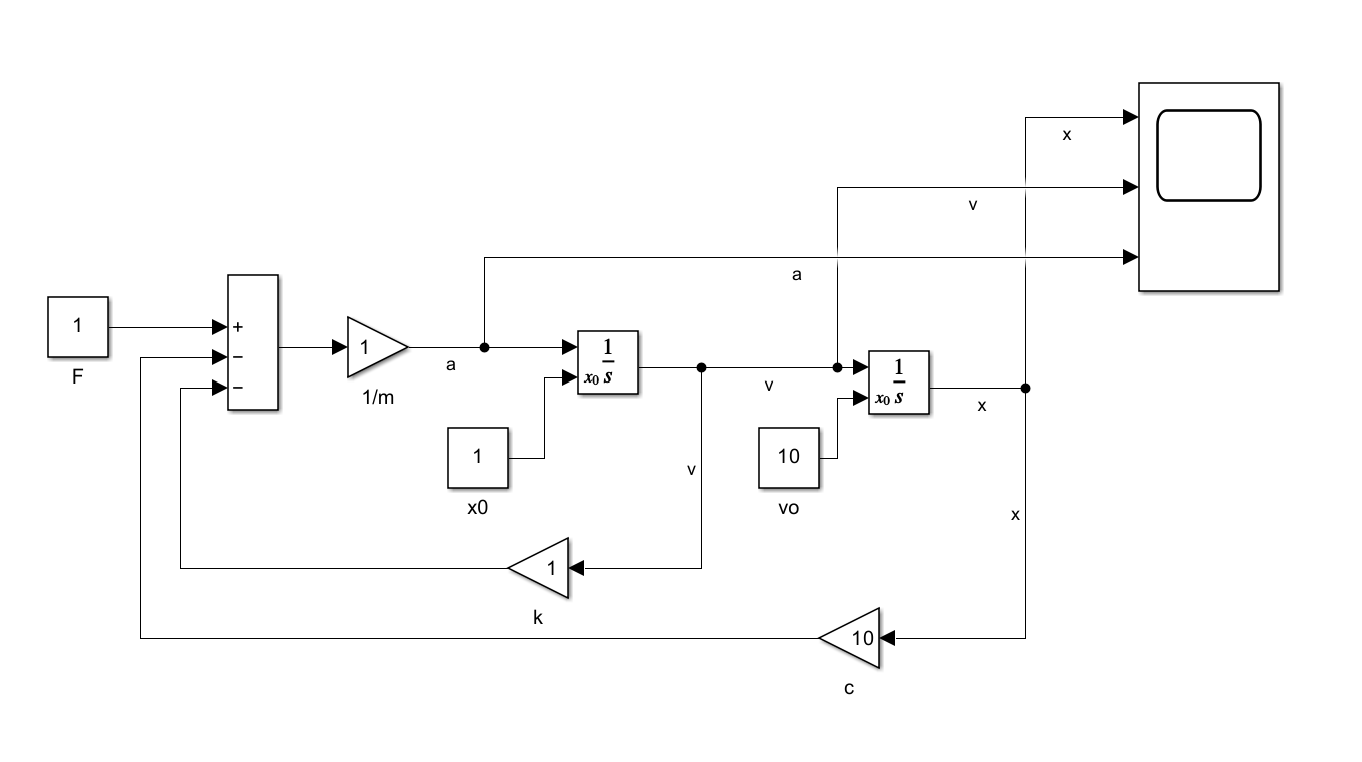

Rys. 5 Schemat blokowy dla układu masa - tłumik - spreżyna w Matlab-Simulink

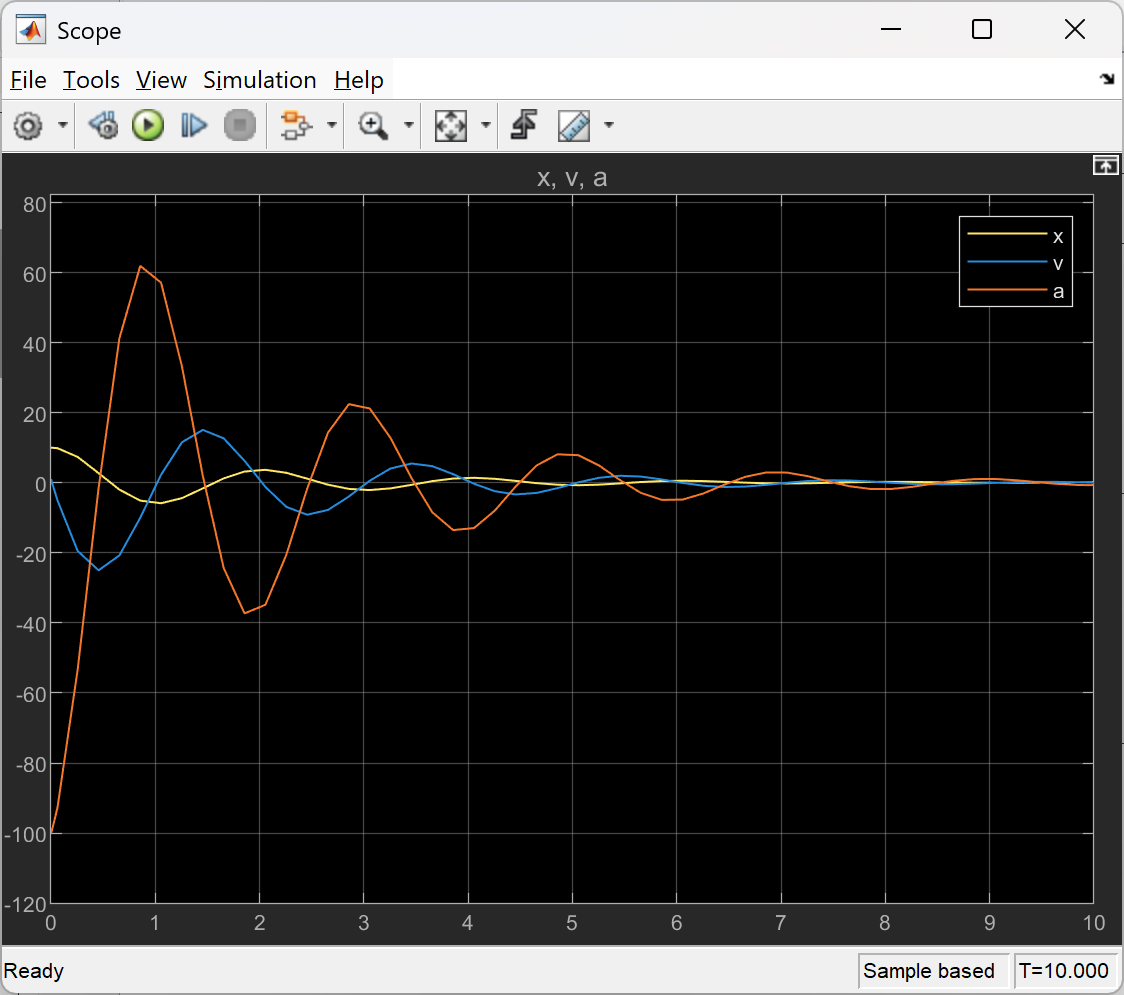

Rys. 6 Wynik symulacji dla układu masa - tłumik - spreżyna w Matlab-Simulink

Druga metoda na zamodelowanie układu w Matlab - Simulink to wykorzystanie równanie w bloku:

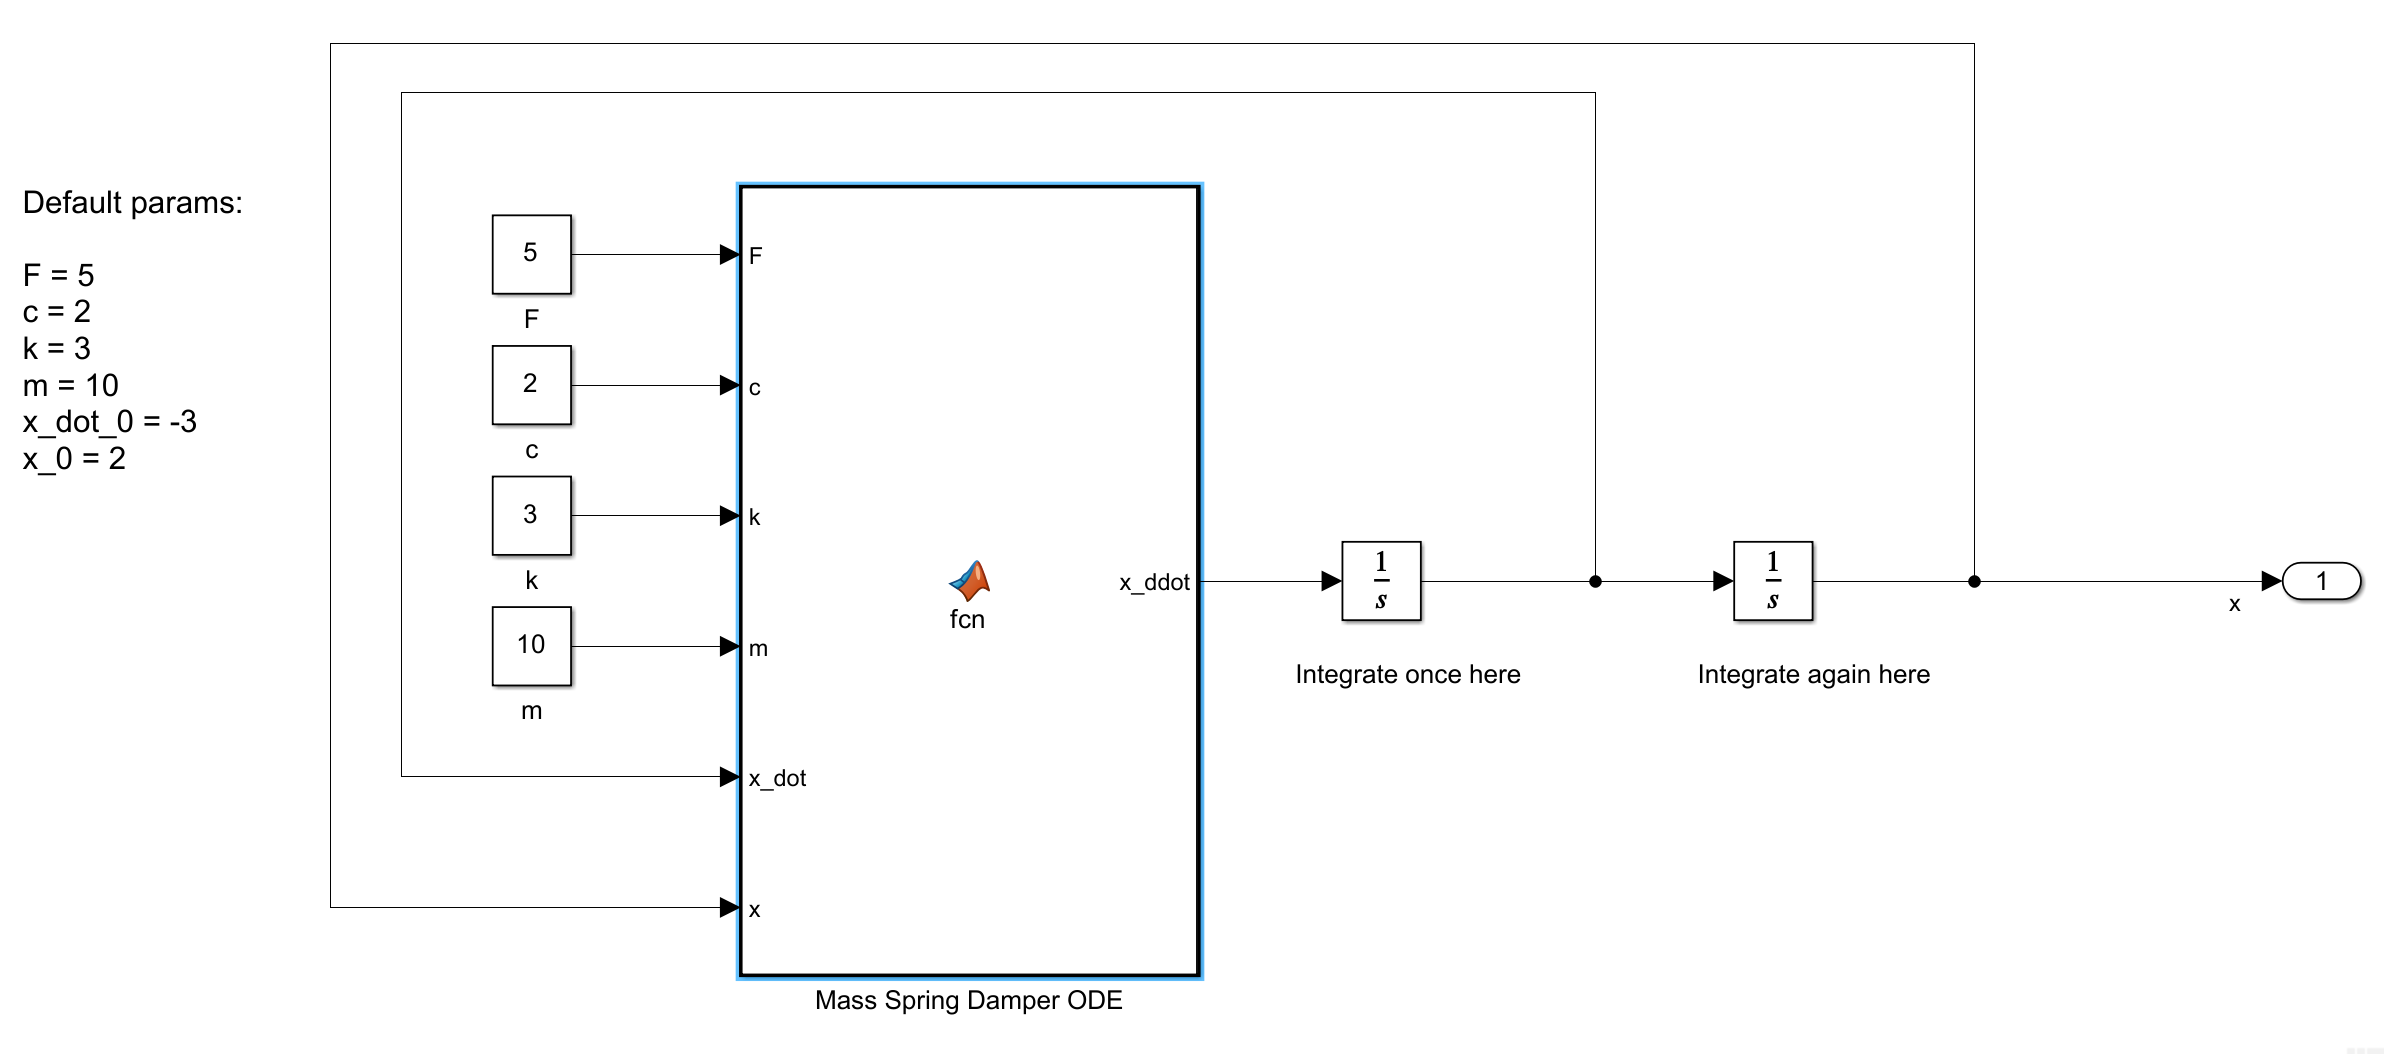

Rys. 7 Scemat blokowy w Matlab-Simulink z wykorzystaniem bloku funkcyjnego

Gdzie blok funkcyjny fcn zawiera równanie ODE:

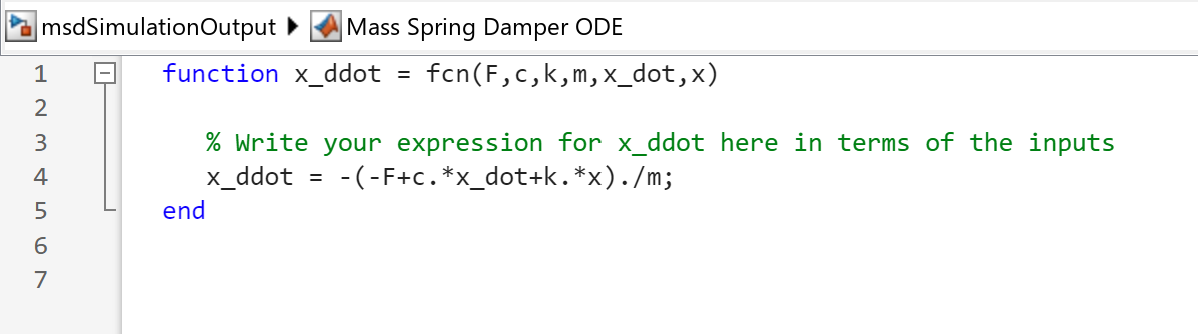

Rys. 8 Równanie ODE zapisane wewnątrz bloku fcn. 

## Przykłądowe zadanie laboratoryjne

   Zamodelować ukłąd z o dwóch stopniach swobody:

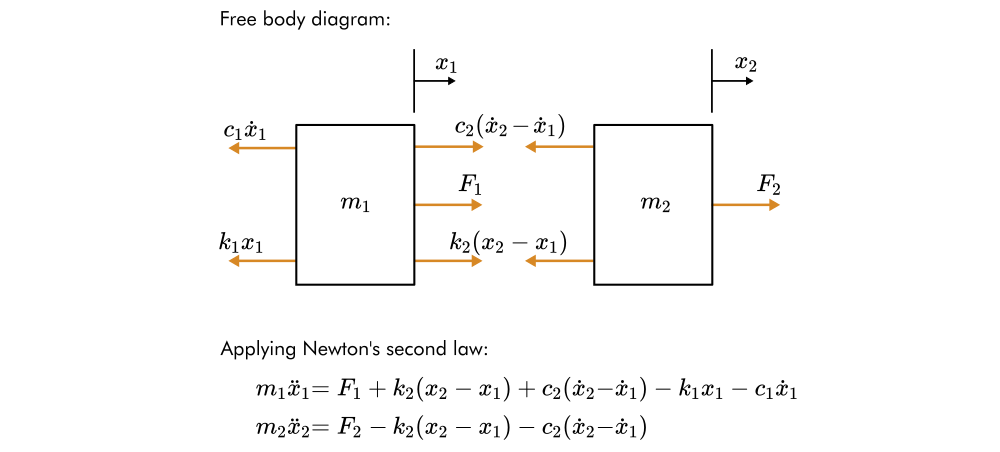

## **PYT: Jak zamodelować, ile stopni swobody ma okręt, pojazd nawodny, pojazd podwodny? **